## Whitening LIGO data (simple)

We will apply a simple whitening scheme to a short segment of data from the LIGO Hanford detector. This is the data segment that contains the first detected GW signal, GW150914.

Whitening requires designing a digital filter with a target transfer function given by,


$$|T(f)| = \frac{1}{\sqrt{S_n(f)}}$$


Here, $S_n(f)$ is an estimate of the PSD obtained from the data itself. If the data used for estimating the target PSD, called training data,  contains a GW signal, the whitening will suppress the signal relative to the noise. Therefore, we must choose the training data  carefully or, as done in LIGO data analysis methods, use some clever approach to reject the contribution of loud transient signals when estimating the PSD. Here, we will simply pick the first 10 sec of the data to estimate the PSD. 

Read the data and get the sampling frequency.

dataVec = h5read('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain');
%Number of samples
nSamples = length(dataVec);
%Sampling interval
samplIntrvl = h5readatt('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain','Xspacing');
%Sampling frequency
samplFreq = 1/samplIntrvl;
%Data duration
dataLen = nSamples/samplFreq;
%Sample times
timeVec = (0:(nSamples-1))/samplFreq;

Suppress the loud power at low frequencies (see [sigprocgwdat](matlab:open('./sigprocgwdat.mlx'))).

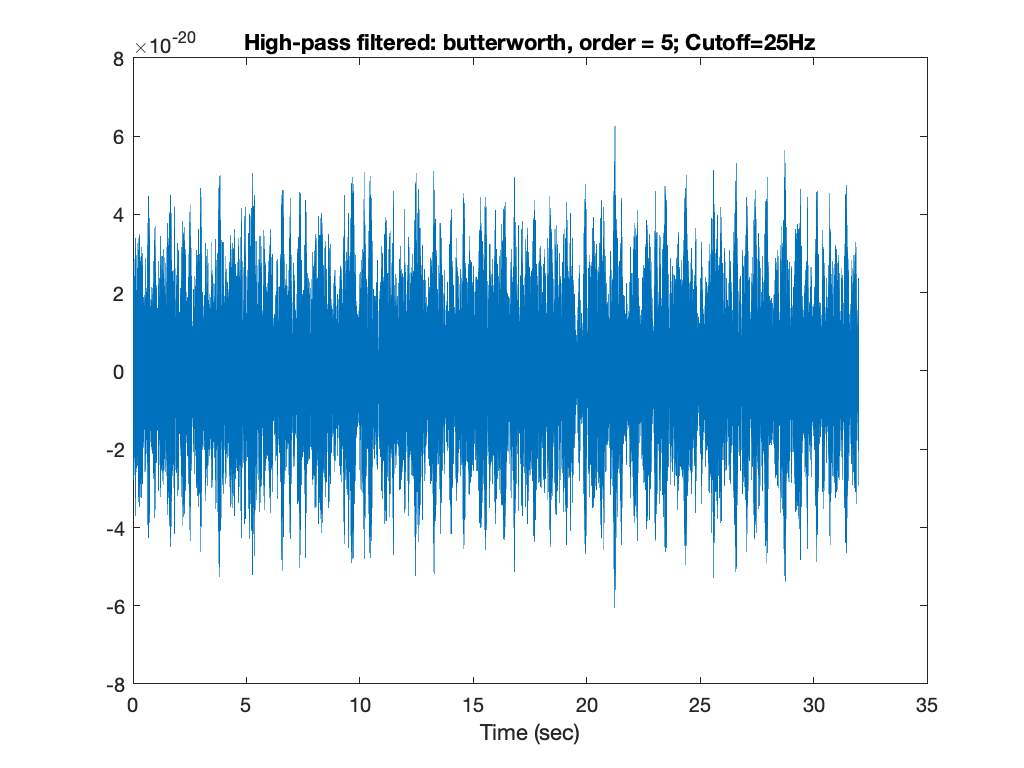

%high-pass frequency cutoff
fHi = 25;%Hz
%high-pass filter type is IIR: Butterworth filter
%Order of butterworth IIR filter
btrFltrOrdr = 5;
[bh,ah] = butter(btrFltrOrdr,fHi/(samplFreq/2),'high');
%Zero-delay filtering
hpDataVec = filtfilt(bh,ah,dataVec);
figure;
plot(timeVec,hpDataVec);
xlabel('Time (sec)');
title(['High-pass filtered: butterworth, order = ',num2str(btrFltrOrdr),...
       '; Cutoff=',num2str(fHi),'Hz']);

Obtain the PSD estimate from the first 10 sec of data. This estimated PSD will be used to design the whitening filter.

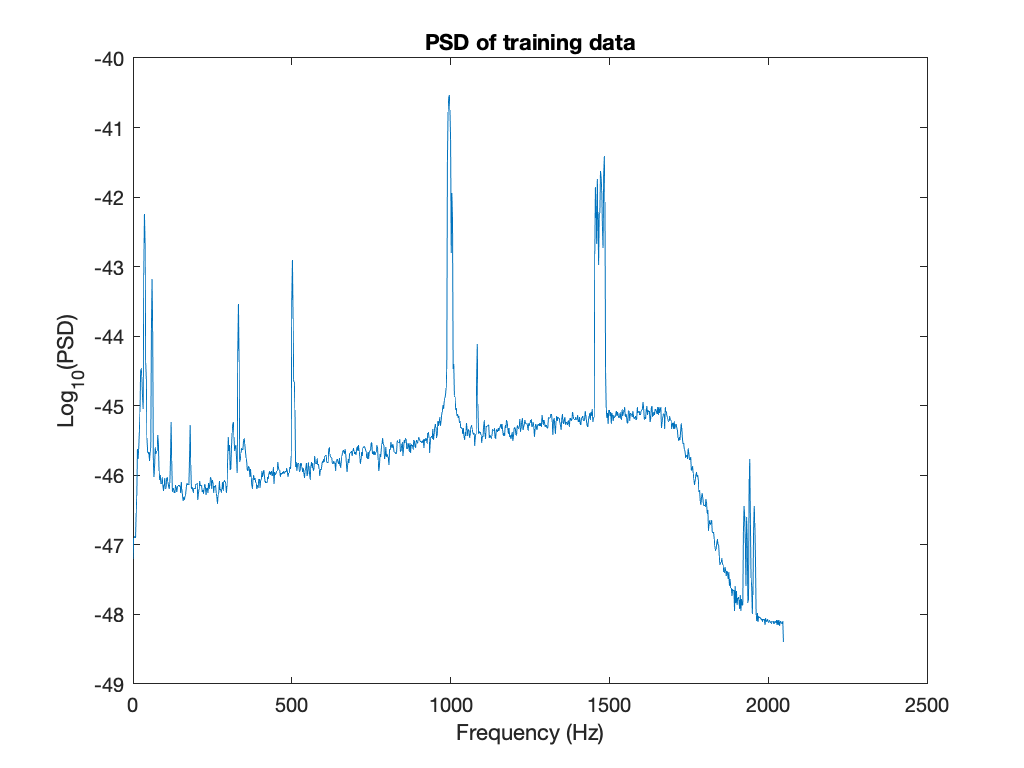

[pxx,fpxx] = pwelch(hpDataVec(1:(floor(10*samplFreq))),floor(0.5*samplFreq),[],[],samplFreq);
figure;
plot(fpxx,log10(pxx));
xlabel('Frequency (Hz)');
ylabel('Log_{10}(PSD)')
title('PSD of training data');

We will only use the frequency range from the high-pass filter cutoff to 1.6 kHz (where GWOSC data has been low-passed already) to design the target transfer function.

whtnTF = ones(size(pxx));
%indices for frequency range
fRangeIndx = fpxx>= fHi & fpxx<=1.6e3;
%Target transfer function
whtnTF(fRangeIndx) = 1./sqrt(pxx(fRangeIndx));
%Filter order
whtnFltrOrdr = 1024;
wb = fir2(whtnFltrOrdr,fpxx/(samplFreq/2), whtnTF);

We can obtain the designed filter's transfer function magnitude.

%Impulse sequence
impVec = zeros(1,nSamples);
impVec(floor(nSamples/4)) = 1;
%Impulse response
impResp = fftfilt(wb,impVec);
%Transfer function
trainWhtTF = abs(fft(impResp));

We can plot the designed filter's transfer function magnitude  and compare with the target function (i.e.,  $\frac{1}{\sqrt{S_n(f)}}$ obtained from the training data) to see if it looks alright.

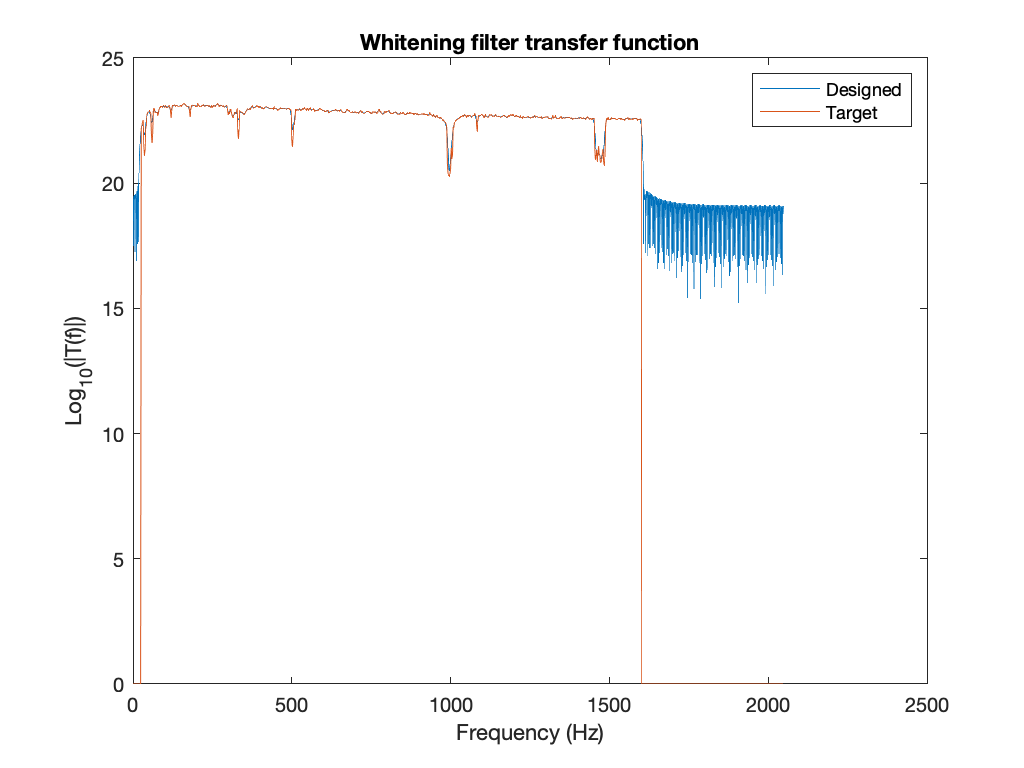

%Positive DFT frequencies
kNyq = floor(nSamples/2)+1;
posFreqDataVec = (0:(kNyq-1))/dataLen;
%Plot filter transfer function
figure;
plot(posFreqDataVec, log10(trainWhtTF(1:kNyq)));
hold on;
plot(fpxx,log10(whtnTF));
legend('Designed','Target')
xlabel('Frequency (Hz)');
ylabel('Log_{10}(|T(f)|)')
title('Whitening filter transfer function')

Apply the whitening filter to the whole data and drop startup transient. 

whtDataVec = fftfilt(wb,dataVec);

Study the whitened data in different domains.

### Time series

tserFig = figure;
plot(timeVec,whtDataVec);

This plot shows a giant filter startup transient! We need to drop it.

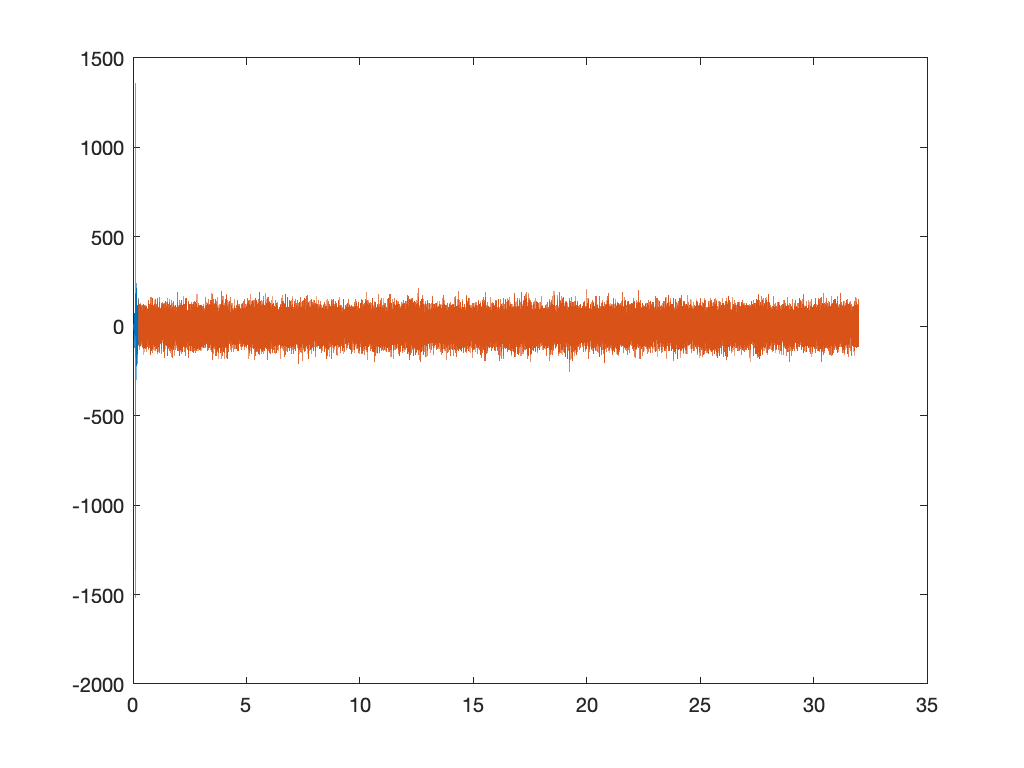

figure(tserFig);
hold on;
plot(timeVec((whtnFltrOrdr+1):end),whtDataVec((whtnFltrOrdr+1):end));

### Spectrum

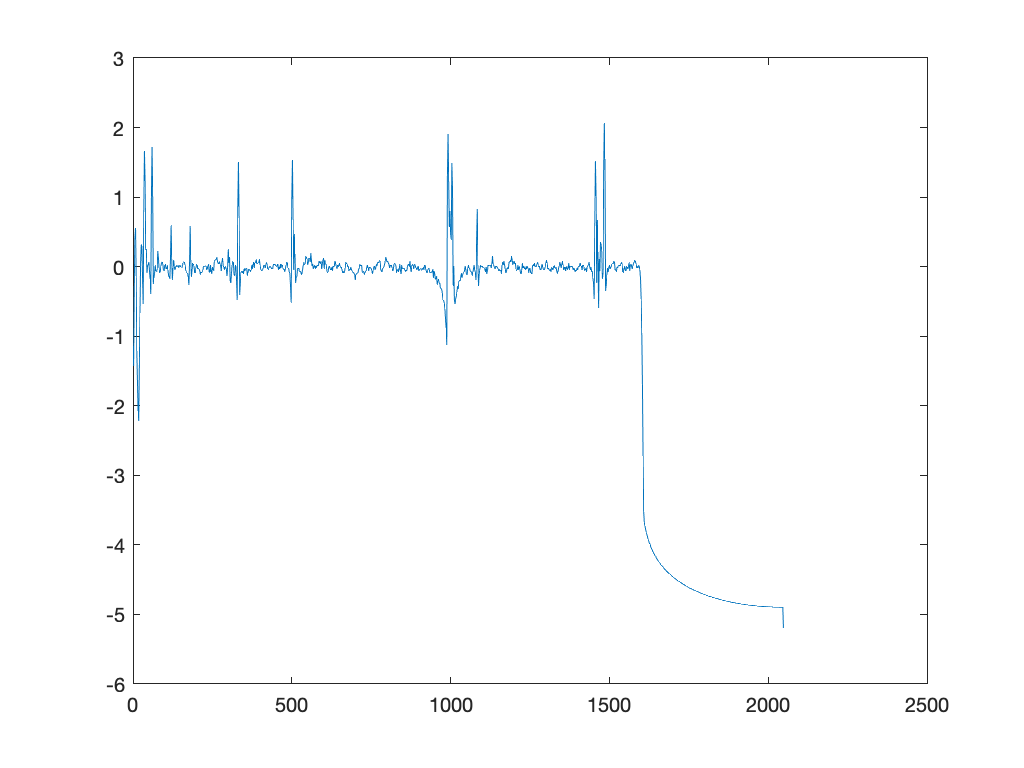

[pxxWD,freqVec] = pwelch(whtDataVec((whtnFltrOrdr+1):end),2048,[],[],samplFreq);
figure;
plot(freqVec,log10(pxxWD));

### Spectrogram

Spectrogram of the data and the whitened data.

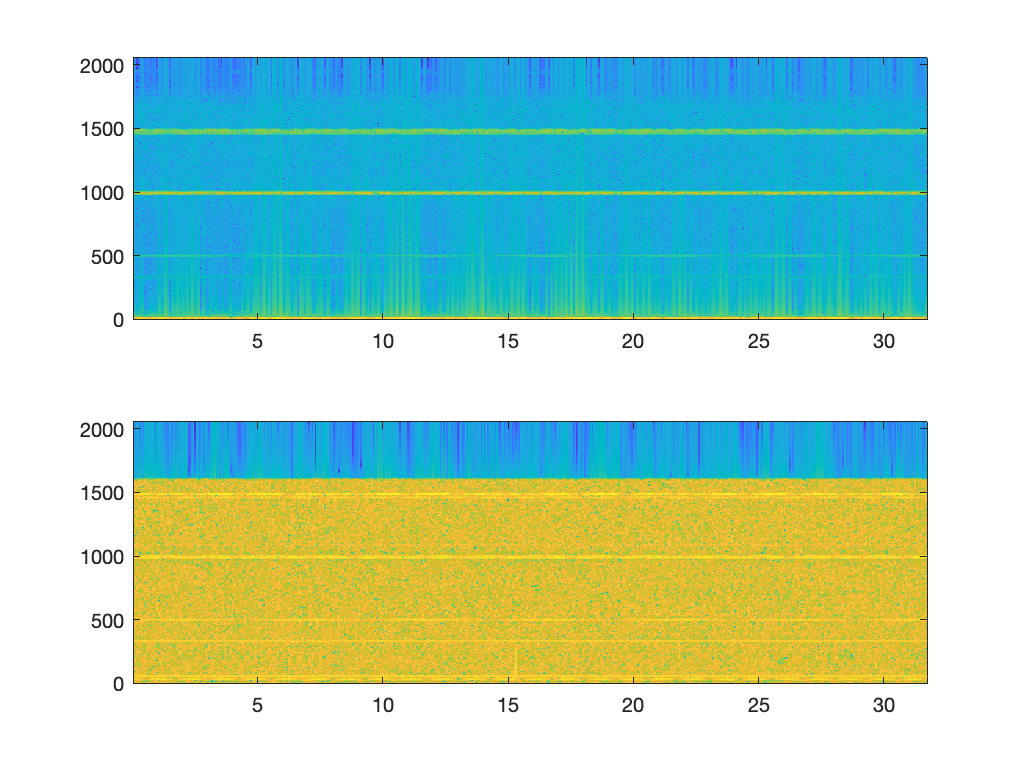

figure;
subplot(2,1,1);
[S,F,T]=spectrogram(dataVec((whtnFltrOrdr+1):end),512,[],[],samplFreq);
imagesc(T,F,log10(abs(S))); axis xy;
subplot(2,1,2);
[S,F,T]=spectrogram(whtDataVec((whtnFltrOrdr+1):end),512,[],[],samplFreq);
imagesc(T,F,log10(abs(S))); axis xy;

### GW signal

If you zoom in around the middle part of the spectrogram, you can see GW150914 now. Plotting the data in the time domain does  not show the signal because of the lines that are still present in the spectrum. However, the frequency band in which most of the signal appears, $\approx [50, 250]$Hz has no loud lines. We can bandpass filter the data to this band and see what we get.

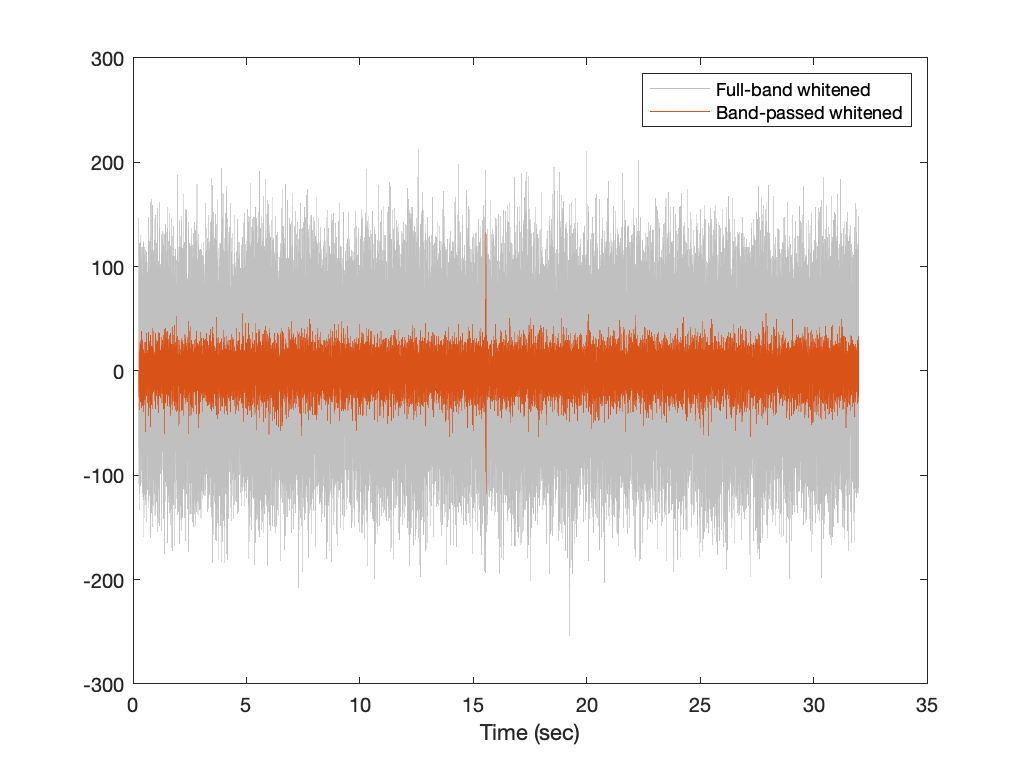

%Filter order
bndPassFltrOrdr = 100;
%Pass-band 
passBand = [50, 250];%Hz
%Design bandpass filter
b = fir1(bndPassFltrOrdr,passBand/(samplFreq/2));
%Filter data
bpDataVec = fftfilt(b,whtDataVec((whtnFltrOrdr+1):end));

figure;
plot(timeVec((whtnFltrOrdr+1):end),whtDataVec((whtnFltrOrdr+1):end),'Color',[192,192,192]/255);
hold on;
plot(timeVec((whtnFltrOrdr+1):end),bpDataVec);
xlabel('Time (sec)');
legend('Full-band whitened','Band-passed whitened');